% Q1 - load dataset
loaded_data = load('Exercise_8_data.mat');
data = loaded_data.data;
event = loaded_data.event;

num_records = numel(data);

% Check for missing/damaged records
damaged_idx = [];
for i = 1:num_records
    x = data(i).x;
    t = data(i).time;
    if any(isnan(x)) || any(isnan(t)) || length(x) ~= length(t)
        damaged_idx(end+1) = i;
    end
end
fprintf('Damaged record(s): %s\n', mat2str(damaged_idx));

Damaged record(s): 57


fprintf('Record %d - NaNs in x: %d, NaNs in time: %d\n', ...
    damaged_idx(1), sum(isnan(data(damaged_idx(1)).x)), sum(isnan(data(damaged_idx(1)).time)));

Record 57 - NaNs in x: 0, NaNs in time: 10001



% Visual Exploration as in class & Log-Log Dynamic Range plot
% ** Set to 'false' to skip over this
run_visual_exploration = false; 

if run_visual_exploration
    f = figure('Name', 'Time Series & Log-Log Dynamic Range Flipbook', 'Position', [100, 100, 1000, 400]); 
    
    for i = 1:num_records
        % Skip damaged Record 57
        if ismember(i, damaged_idx)
            continue; 
        end
        
        figure(f);
        
        % Left Subplot: Standard Time Series Trace
        subplot(1, 2, 1);
        plot(data(i).time, data(i).x, 'b');
        grid on;
        title(sprintf('Record %d of %d (Time Series Trace)', i, num_records));
        xlabel('Time'); 
        ylabel('Amplitude (x)');
        
        % Right Subplot: Log-Log Dynamic Range Check
        % Sort absolute amplitudes in descending order to test for power-law structure
        x_mag = sort(abs(data(i).x), 'descend');
        
        subplot(1, 2, 2);
        loglog(x_mag, 'r', 'LineWidth', 1.5);
        grid on;
        title(sprintf('Record %d Log-Log Dynamic Range', i));
        xlabel('Rank Index (Log Scale)'); 
        ylabel('|Amplitude| (Log Scale)');
        
        pause(0.5); 
    end
end

% Dynamic range across records
mins = zeros(num_records, 1);
maxs = zeros(num_records, 1);
spans = zeros(num_records, 1);
iqrs  = zeros(num_records, 1);

for i = 1:num_records
    mins(i) = min(data(i).x);
    maxs(i) = max(data(i).x);
    spans(i) = maxs(i) - mins(i);

    % IQR (Q3 - Q1) measures the middle 50% of data to protect against outliers
    iqrs(i)  = iqr(data(i).x); 
end

fprintf('--- Dynamic Range Summary across %d records ---\n', num_records);

--- Dynamic Range Summary across 100 records ---


fprintf('Linear Span (max - min): min = %.2f, max = %.2f, mean = %.2f\n', ...
    min(spans), max(spans), mean(spans));

Linear Span (max - min): min = 97.39, max = 279.51, mean = 161.08


fprintf('IQR (Q3 - Q1)   : min = %.2f, max = %.2f, mean = %.2f\n', ...
    min(iqrs), max(iqrs), mean(iqrs));

IQR (Q3 - Q1)   : min = 5.20, max = 70.37, mean = 25.43




% Sampling interval check (skip damaged Record 57)
valid_idx = setdiff(1:num_records, damaged_idx);
dt_mean   = zeros(length(valid_idx), 1);
dt_std    = zeros(length(valid_idx), 1);
dt_min_raw = zeros(length(valid_idx), 1);
dt_min_robust = zeros(length(valid_idx), 1);
zero_dt_count = 0;

for k = 1:length(valid_idx)
    dt = diff(data(valid_idx(k)).time);
    
    % Check for duplicate timestamps (dt == 0)
    zero_dt_count = zero_dt_count + sum(dt == 0);
    
    % Filter only positive intervals (dt > 0)
    pos_dt = dt(dt > 0);
    
    dt_mean(k) = mean(pos_dt);
    dt_std(k)  = std(pos_dt);
    
    % Raw absolute minimum (vulnerable to rare clock stutters)
    dt_min_raw(k) = min(pos_dt);
    
    % "Within Reason" Robust Minimum: 1st percentile ignores rare bottom 1% stutters
    dt_min_robust(k) = prctile(pos_dt, 1); 
end

fprintf('--- Sampling Interval Characteristics ---\n');

--- Sampling Interval Characteristics ---


fprintf('Total duplicate timestamps (dt == 0) found across records: %d\n', zero_dt_count);

Total duplicate timestamps (dt == 0) found across records: 99


fprintf('Mean sampling interval range    : [%.2f, %.2f]\n', min(dt_mean), max(dt_mean));

Mean sampling interval range    : [10.00, 10.00]


fprintf('Sampling interval std range     : [%.2f, %.2f]\n', min(dt_std), max(dt_std));

Sampling interval std range     : [2.19, 3.00]


fprintf('Avg coefficient of variation    : %.1f%%\n', mean(dt_std ./ dt_mean) * 100);

Avg coefficient of variation    : 26.2%


fprintf('Raw minimum interval range      : [%.5f, %.5f] (Would cause RAM explosion!)\n', min(dt_min_raw), max(dt_min_raw));

Raw minimum interval range      : [0.00257, 2.48705] (Would cause RAM explosion!)


fprintf('Robust minimum ("within reason"): [%.2f, %.2f] (1st percentile threshold)\n', min(dt_min_robust), max(dt_min_robust));

Robust minimum ("within reason"): [2.92, 5.00] (1st percentile threshold)




% Quantization check - Count unique amplitude values (Task 1d, bullet 3)
dup_frac   = zeros(num_records, 1);
num_unique = zeros(num_records, 1);
min_delta  = zeros(num_records, 1);

for i = 1:num_records
    x = data(i).x;
    u_vals = unique(x);
    
    num_unique(i) = length(u_vals);
    dup_frac(i)   = 1 - num_unique(i) / length(x);
    
    % Find empirical quantization step size (minimum difference between unique values)
    min_delta(i)  = min(diff(u_vals));
end

fprintf(' Coarse Quantization Check:\n');

 Coarse Quantization Check:


fprintf('Unique amplitude count range : [%d, %d] out of ~10,000 samples\n', min(num_unique), max(num_unique));

Unique amplitude count range : [10001, 10001] out of ~10,000 samples


fprintf('Max duplicate-value fraction : %.4f\n', max(dup_frac));

Max duplicate-value fraction : 0.0000


fprintf('Empirical min step size (Δ)  : min = %.2e, max = %.2e\n', min(min_delta), max(min_delta));

Empirical min step size (Δ)  : min = 2.58e-09, max = 2.20e-06


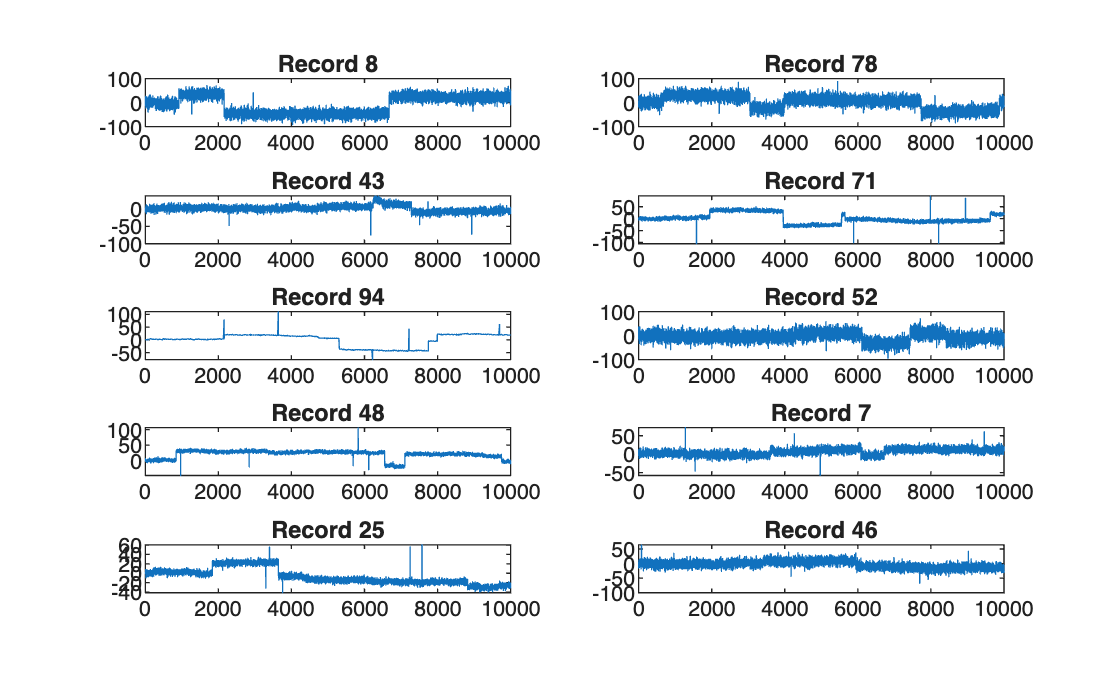



% Plot 10 randomly selected records
rng(7);
sample_idx = randperm(num_records, 10);

figure;
for k = 1:10
    subplot(5, 2, k);
    plot(data(sample_idx(k)).x);
    title(sprintf('Record %d', sample_idx(k)));
end

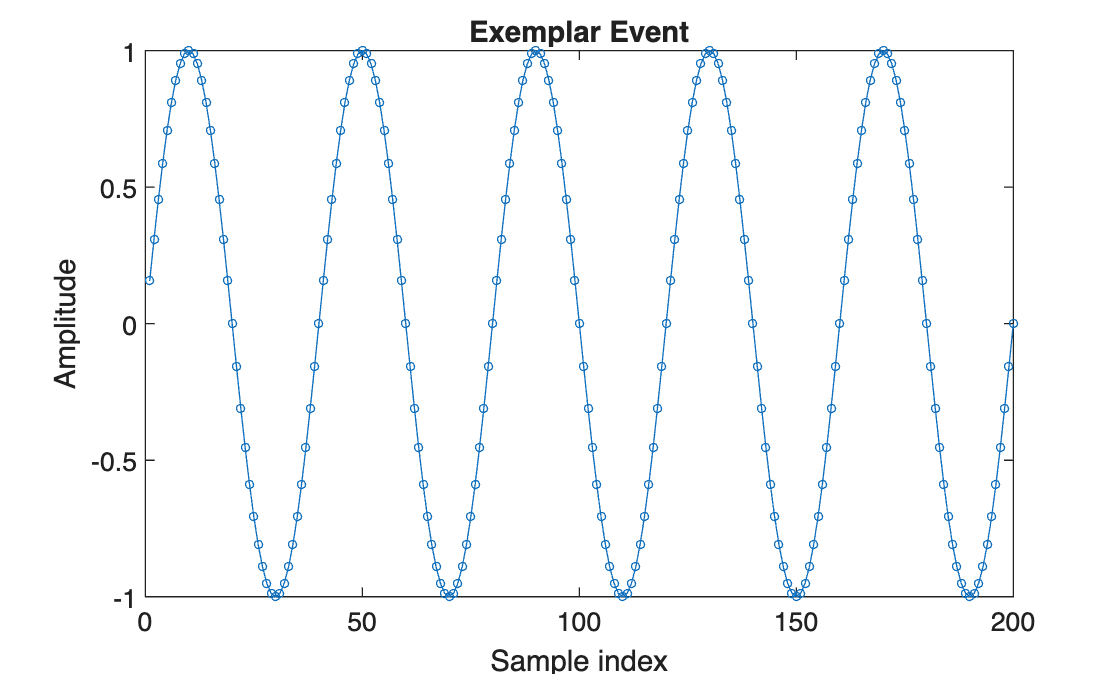


% Plot the event
figure;
plot(event, '-o', 'MarkerSize', 3);
title('Exemplar Event');
xlabel('Sample index'); ylabel('Amplitude');

Record 57 contains erroneous data, its time vector is entirely NaN even though the measurement data itself is fine, suggesting a timestamp logging fault rather than a sensor fault. Because accurate time intervals are mandatory for signal processing, record 57 is formally excluded from analysis. All remaining 99 records are kept.

Dynamic range varies a fair bit record to record, ranging from roughly 100 to 280, so normalization should probably be done per-record rather than globally. Furthermore, comparing this linear span to the interquartile range, yielded a ratio of 6.3. The IQR is immune to single-sample outliers, whereas the min-max peak-to-peak span is not, and so this ratio gives us a sense of how many outliers we have. Even without calculating this ratio, our visual flipping through the data made it obvious that these exist and need to be removed. Finally, we created log-log plots of the histograms of the amplitude against the rank-index. This plot confirmed a linear dynamic range with flat curves that steeply fall at the far right edge.

Analysis of the inter-arrival times led to 3 notable insights. First, every valid record shows a mean sampling interval of about 10, but with a standard deviation around 25–30% of that, this is genuinely stochastic sampling, consistently across the whole dataset, not just a few noisy records. Second, every single record had one pair of samples with identical timestamps. These need to be de-duplicated prior to interpolation. Finally, to correct for stochastic sampling, we need to interpolate the data onto a uniform time grid. As we discussed, using the absolute raw minimum interval (~0.00257) wouldn't be practical, as it would expand a single record into 39 million samples. Instead, we use the 1st percentile of positive intervals to get a reasonable minimum arrival time of 3.88.

Evaluating the ratio of unique amplitude values confirmed that there is no coarse quantization. Every record contains between 9,998 and 10,001 unique values out of 10,000 samples, exceeding the 64-cell threshold required to resolve the signal. Following Bennett's (1948) theorem, the empirical quantization step size (~10^-15) is much smaller than the signal variance, allowing quantization error to be treated as white noise.

Visual inspection of the records show that the same basic statistical class seems to be present among them. We do see three different kinds of artifacts: 1. isolated outlier spikes , as noted above. We can use median filtering to remove these. 2. Varying amounts of background noise per time series, which can be addressed via wavelet denoising. 3. Sudden vertical level shifts, with the underlying physical signal unchanged on both sides of the jump (stationarity holds). These appear to be sensor issues that can be subtracted out of the signal.

The event itself is a clean, smooth, ~5-cycle sinusoidal burst with no noise, easy to recognize in isolation, but given the noise, spikes and shifts noted above in the records, finding it reliably embedded in real data is a different problem entirely. Stochastic sampling will also stretch and compress the event's time duration between time series, causing misalignment that will make this difficult.

% Q2 - Baseline Assessment: Vectorized Matched Filtering on Raw Data
L = length(event);

% Pre-normalize the event template
y_zero = event - mean(event);
y_norm = y_zero / norm(y_zero);

best_corr = zeros(num_records, 1);
best_pos  = zeros(num_records, 1);

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    x = data(i).x;
    
    % Vectorized Numerator (Sliding dot product via fast convolution)
    num_vec = conv(x, fliplr(y_norm), 'valid');
    
    % Vectorized Denominator (Sliding local L2 norm via moving standard deviation)
    den_vec = sqrt(L - 1) * movstd(x, [L-1, 0], 'Endpoints', 'discard');
    
    % Compute normalized correlation coefficient for all indices
    corrs = num_vec ./ (den_vec + eps);
    
    [best_corr(i), best_pos(i)] = max(corrs);
end

% Find global maximum correlation across the entire dataset
[global_max_corr, best_record] = max(best_corr);
global_best_pos = best_pos(best_record);

fprintf('Vectorized Matched Filter Results (Step Size = 1) \n');

Vectorized Matched Filter Results (Step Size = 1) 


fprintf('Max correlation across all records: %.4f (found in Record %d at Index %d)\n', ...
    global_max_corr, best_record, global_best_pos);

Max correlation across all records: 0.7140 (found in Record 65 at Index 6869)



% Grab the 10 strongest matches
[sorted_corr, sort_idx] = sort(best_corr, 'descend');
top10_records = sort_idx(1:10);
top10_pos = best_pos(top10_records);

fprintf('Top 10 Matched Filter Matches on Raw Data:\n');

Top 10 Matched Filter Matches on Raw Data:


for k = 1:10
    fprintf('  %2d. Record %2d at Index %5d | Correlation: %.4f\n', ...
        k, top10_records(k), top10_pos(k), sorted_corr(k));
end

   1. Record 65 at Index  6869 | Correlation: 0.7140
   2. Record  8 at Index  3957 | Correlation: 0.6848
   3. Record 53 at Index  1980 | Correlation: 0.6745
   4. Record 66 at Index  8857 | Correlation: 0.6733
   5. Record 64 at Index  2107 | Correlation: 0.6727
   6. Record 23 at Index  8437 | Correlation: 0.6708
   7. Record 77 at Index   727 | Correlation: 0.6656
   8. Record 90 at Index  9760 | Correlation: 0.6567
   9. Record 98 at Index  2871 | Correlation: 0.6532
  10. Record 34 at Index  3402 | Correlation: 0.6528


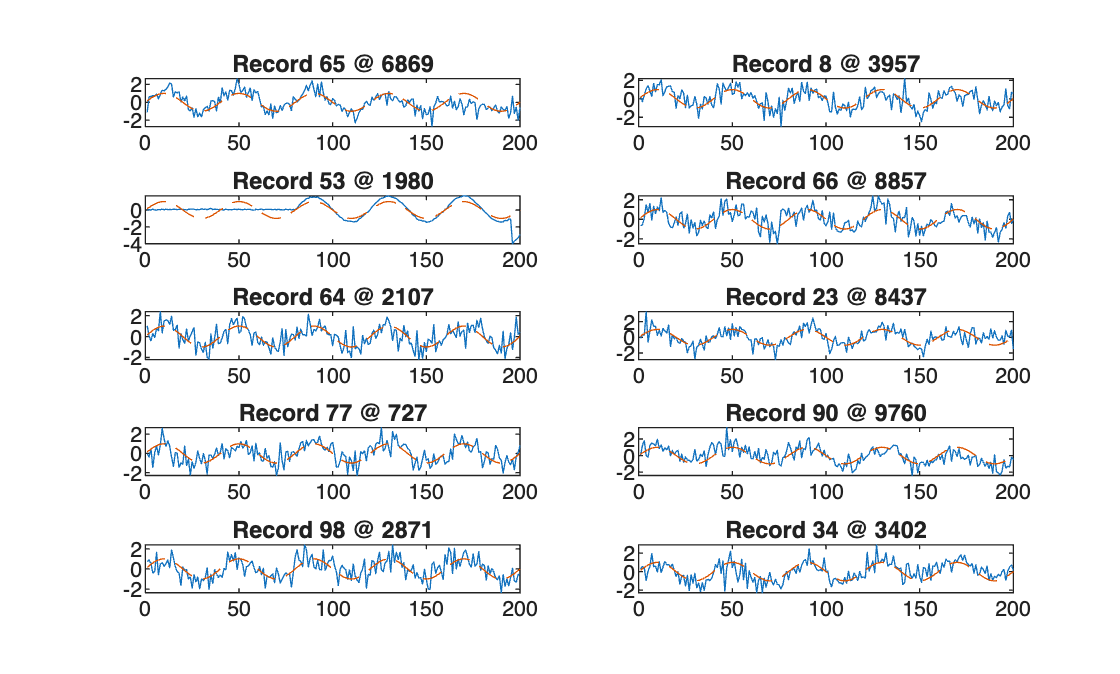


% Plot the 10 found examples against the event template
figure;
for k = 1:10
    subplot(5, 2, k);
    rec = top10_records(k);
    pos = top10_pos(k);
    seg = data(rec).x(pos:pos+L-1);
    seg_z = (seg - mean(seg)) / std(seg);
    plot(seg_z); hold on;
    plot(event, '--');
    title(sprintf('Record %d @ %d', rec, pos));
    hold off;
end

The strongest matches reach correlation coefficients around 0.65 to 0.71. In a match, these should be close to 1.0, which tells us right away that no occurrence of the event in the actual data is a clean, unaltered copy of the event. However, the plot of the ten best matches do show that the signal is more or less matched but with a lot of noise present, accounting for the correlation maxing out at 0.71.

So the 10 highest-scoring windows do have sinusoidal oscillations and they do generally match the shape of the event. However, none of the 10 examples are identical to any other, nor do they perfectly match the event. Some records show drift where they match the event more closely at the start but drift further away near the end: Records 65 and 90 both drift downward slightly by the end.

To build a system to automatically detect events, a vectorized sliding matched filter using convolution would scan all window positions at once rather than via a loop. This allows us to work on huge datasets without manual inspection. However, it wouldn't be able to detect all variations. The matched filter works very well if we know the exact shape of the signal we are detecting. Stochastic sampling distorts the event's frequency in sample space. Also, vertical shifts occurring within a window would corrupt mean and standard deviation estimates in normalization, causing filter mismatches. If we want to reliably detect all variations, preprocessing must be done including denoising, resampling to a uniform time grid and level-shift correction.

A neural network by itself isn't a good solution here either. We only have ~100 records total, giving very few labeled true-positive examples to train on, nowhere near enough for a network to learn robust invariance to amplitude scaling, timing jitter, and noise on its own. A plain feedforward network has no built-in translation or time-warp invariance, so it would need to see the event at every possible position/scale/noise condition during training to generalize, which this dataset can't provide. A correlation/matched-filter approach, by contrast, directly exploits the fact that we already know the exact shape we're looking for and needs no training data at all; it's simpler, more data-efficient, and more interpretable for this specific problem.

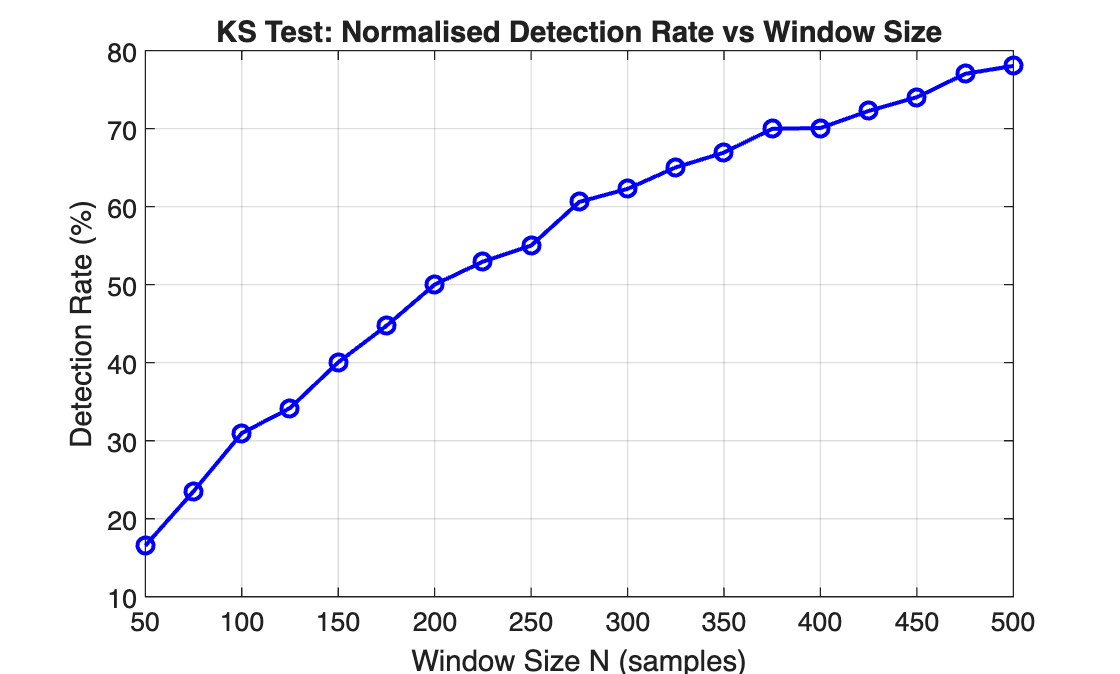

% Q3 Sweep window sizes finely to find the sweet spot for KS test
% FEEDBACK: Run the loop from right to left
window_sizes = 50:25:500;
alpha = 0.05;
detection_rate = zeros(length(window_sizes), 1);

for wi = 1:length(window_sizes)
    w = window_sizes(wi);
    total_tests = 0;
    total_detections = 0;
    
    for i = 1:num_records
        if ismember(i, damaged_idx)
            continue;
        end
        x = data(i).x;
        n = length(x);
        
        % Right-to-left pass; start from the rightmost window pair ending
        % at n
        start_j = n - (2 * w) + 1;
        for j = start_j : -w :1
            if j < 1
                break;
            end

            win1 = x(j     : j +   w - 1);
            win2 = x(j + w : j + 2*w - 1);
            [~, p] = kstest2(win1, win2);
            total_tests = total_tests + 1;
            if p < alpha
                total_detections = total_detections + 1;
            end
        end
    end
    
    detection_rate(wi) = total_detections / total_tests;
end

figure('Name', 'KS Test Detection Rate vs Window Size');
plot(window_sizes, detection_rate * 100, 'b-o', 'LineWidth', 1.5);
grid on;
xlabel('Window Size N (samples)');
ylabel('Detection Rate (%)');
title('KS Test: Normalised Detection Rate vs Window Size');



% Stationarity Testing via Two-Sample KS Test
N_win = 100;   % Window size chosen from power analysis
alpha = 0.05;  % Significance level
stride = N_win; % Non-overlapping windows for independent comparisons

% Pre-allocate summary statistics
pct_rejected = zeros(num_records, 1); % Fraction of window pairs rejecting H0

figure('Name', 'Q3: KS Stationarity Test - P-Value Profiles (Right-to-left)');

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    x = data(i).x;
    n = length(x);

    % Slide two adjacent windows from right to left at stride = N_win
    positions = [];
    p_vals    = [];

    % Right-to-left pass: Start from the tail end of the record and step
    % backwards
    start_j = n - (2 * N_win) + 1;

    for j = start_j : -stride : 1
        if j < 1
            break;
        end

        win1 = x(j          : j +   N_win - 1);
        win2 = x(j + N_win  : j + 2*N_win - 1);

        [~, p] = kstest2(win1, win2);

        positions(end+1) = j + N_win; %#ok<SAGROW> Midpoint between the two windows
        p_vals(end+1)    = p;         
    end

    pct_rejected(i) = mean(p_vals < alpha) * 100;
end

% Summary across all valid records
fprintf('--- Q3 Stationarity Testing Summary (Right-to-left, N = %d, alpha = %.2f) ---\n', N_win, alpha);

--- Q3 Stationarity Testing Summary (Right-to-left, N = 100, alpha = 0.05) ---


fprintf('Mean rejection rate across records : %.1f%%\n', mean(pct_rejected(pct_rejected > 0)));

Mean rejection rate across records : 31.0%


fprintf('Min rejection rate                 : %.1f%%\n', min(pct_rejected(pct_rejected > 0)));

Min rejection rate                 : 8.1%


fprintf('Max rejection rate                 : %.1f%%\n', max(pct_rejected(pct_rejected > 0)));

Max rejection rate                 : 96.0%


fprintf('Records with > 50%% rejection rate  : %d of 99\n', sum(pct_rejected > 50));

Records with > 50% rejection rate  : 15 of 99


fprintf('Records with < 10%% rejection rate  : %d of 99\n', sum(pct_rejected > 0 & pct_rejected < 10));

Records with < 10% rejection rate  : 2 of 99


A two-sample Kolmogorov-Smirnov test was applied to adjacent non-overlapping windows sliding across each of the 99 valid records. A window size of 100 was chosen because this is a small enough window size that can still provide enough statistical power (at alpha = 0.05). We plotted window size against KS test detection rate, and no plateau or elbow was seen, which confirms that there is no optimal window size to choose, which is why we defaulted to 100.

The average rejection rate across all records was 31.0%, much higher than the 5% expected under H0, that the signal is stationary. In fact, even the minimum rejection rate across all 99 time series was higher than 5% (at 8.1%). Therefore, the data cannot be modeled as arising from a stationary (or ergodic) process. Since ergodicity requires stationarity, it is ruled out as well. We noted vertical level-shifts in Q1 and this is the likely source of the non-stationarity that we see here.

% Q4 - Characterize the stochastic sampling distribution
all_dts = [];

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    dt = diff(data(i).time);

    % Keep only positive intervals (exclude duplicate timestamps dt == 0)
    all_dts = [all_dts; dt(dt > 0)];
end

% Apply 1st percentile "within reason" threshold from Q1
dt_threshold = prctile(all_dts, 1);
valid_dts = all_dts(all_dts >= dt_threshold);

fprintf('--- Stochastic Sampling Distribution Characteristics ---\n');

--- Stochastic Sampling Distribution Characteristics ---


fprintf('Total valid intervals : %d\n', length(valid_dts));

Total valid intervals : 979902


fprintf('Mean  (mu)            : %.4f\n', mean(valid_dts));

Mean  (mu)            : 10.0681


fprintf('Std   (sigma)         : %.4f\n', std(valid_dts));

Std   (sigma)         : 2.5495


fprintf('CoV                   : %.1f%%\n', std(valid_dts)/mean(valid_dts)*100);

CoV                   : 25.3%


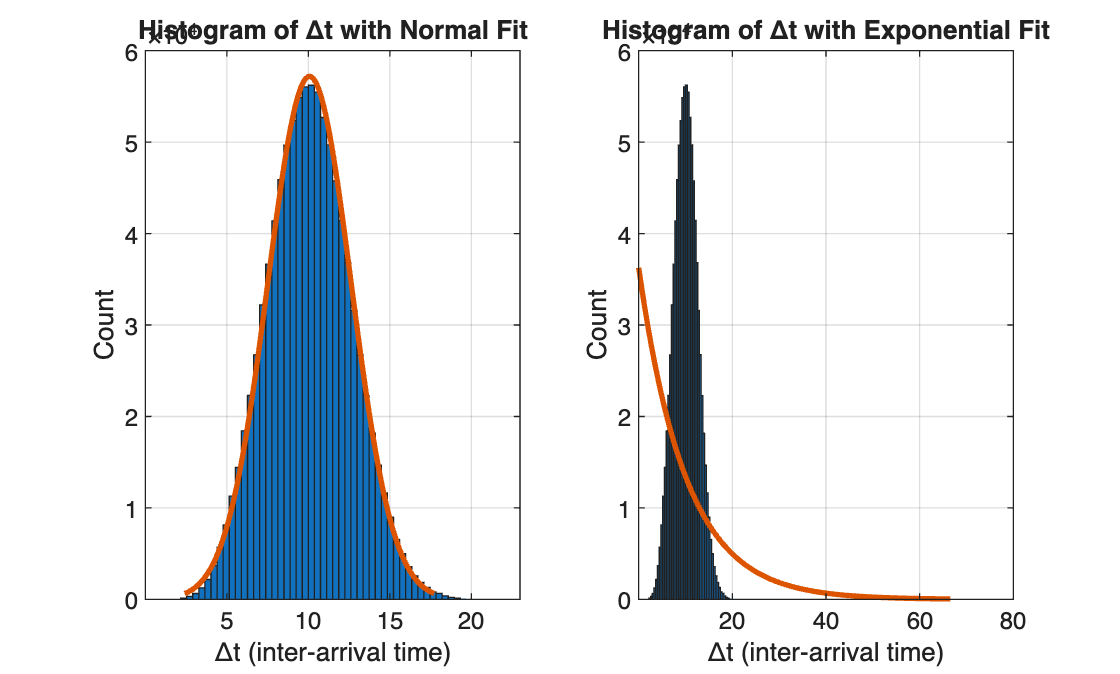


% Plot histogram with Normal and Exponential fits side-by-side
figure('Name', 'Q4: Stochastic Sampling Distribution');

subplot(1, 2, 1);
histfit(valid_dts, 60, 'normal');
title('Histogram of \Deltat with Normal Fit');
xlabel('\Deltat (inter-arrival time)'); ylabel('Count');
grid on;

subplot(1, 2, 2);
histfit(valid_dts, 60, 'exponential');
title('Histogram of \Deltat with Exponential Fit');
xlabel('\Deltat (inter-arrival time)'); ylabel('Count');
grid on;


% Formal KS goodness-of-fit test against Normal distribution
% Z-score the valid_dts and test against standard normal
dts_zscore = (valid_dts - mean(valid_dts)) / std(valid_dts);
[h_normal, p_normal, ksstat] = kstest(dts_zscore);
fprintf('KS statistic D        : %.6f (max CDF deviation = %.4f%%)\n', ksstat, ksstat * 100);

KS statistic D        : 0.007338 (max CDF deviation = 0.7338%)


fprintf('KS D_critical at 0.05 : %.6f (N = %d)\n', 1.36 / sqrt(length(dts_zscore)), length(dts_zscore));

KS D_critical at 0.05 : 0.001374 (N = 979902)



fprintf('\n--- KS Goodness-of-Fit Test ---\n');


--- KS Goodness-of-Fit Test ---


fprintf('Normal distribution  : h = %d, p = %.4f ', h_normal, p_normal);

Normal distribution  : h = 1, p = 0.0000 

if h_normal == 0
    fprintf('(FAIL TO REJECT: data is consistent with Gaussian)\n');
else
    fprintf('(REJECT: data is NOT Gaussian)\n');
end

(REJECT: data is NOT Gaussian)


The visual histogram plot suggests that the distribution of inter-arrival times is Gaussian. To formally test this, a KS test was done with D = 0.0073, p = 0); however, with a large sample of about 980,000 intervals, The critical threshold for the D statistic was 0.0014, which means CDF deviations above 0.14% are flagged as significantly different. Our observed deviation is 0.73%, which is practically negligible. In any case, even with a non-Gaussian distribution, the coefficient of variance (CoV) of 25.3% indicates that there is enough stochastic variability to cause problems for matched filtering.

% Q5 - Identify which records have stochastic sampling (should be all)
cov_threshold = 0.05; % 5% CoV threshold for stochastic classification

is_stochastic  = false(num_records, 1);
per_rec_cov    = zeros(num_records, 1);
per_rec_dtmin  = zeros(num_records, 1);
per_rec_dtmean = zeros(num_records, 1);

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    dt     = diff(data(i).time);
    pos_dt = dt(dt > 0);

    mu_dt  = mean(pos_dt);
    sig_dt = std(pos_dt);
    cov_i  = sig_dt / mu_dt;

    per_rec_cov(i)    = cov_i;
    per_rec_dtmean(i) = mu_dt;

    % "Within reason" robust minimum for this specific record
    per_rec_dtmin(i) = prctile(pos_dt, 1);

    is_stochastic(i) = (cov_i > cov_threshold);
end

stochastic_idx = find(is_stochastic);
constant_idx   = setdiff(find(~is_stochastic), damaged_idx);

fprintf('--- Q5: Per-Record Stochastic Sampling Classification ---\n');

--- Q5: Per-Record Stochastic Sampling Classification ---


fprintf('Records classified as stochastic (CoV > %.0f%%): %d of 99\n', ...
    cov_threshold * 100, length(stochastic_idx));

Records classified as stochastic (CoV > 5%): 99 of 99


fprintf('Records classified as constant sampled          : %d of 99\n', ...
    length(constant_idx));

Records classified as constant sampled          : 0 of 99


fprintf('Per-record CoV range: [%.1f%%, %.1f%%]\n', ...
    min(per_rec_cov(per_rec_cov > 0)) * 100, max(per_rec_cov) * 100);

Per-record CoV range: [21.9%, 30.0%]




% Next: Resample all stochastic records onto a uniform time grid
% Store resampled data in a new struct to keep raw data intact
data_resampled(num_records) = struct('time', [], 'x', []);

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end

    % De-duplicate identical timestamps (keep first occurrence)
    [t_unique, idx_unique] = unique(data(i).time, 'first');
    x_unique = data(i).x(idx_unique);

    %  Build uniform time grid using this record's robust dt_min
    dt_min = per_rec_dtmin(i);
    t_grid = t_unique(1) : dt_min : t_unique(end);

    % Spline interpolation (cubic polynomial approx) onto the uniform grid
    x_grid = interp1(t_unique, x_unique, t_grid, 'spline');

    data_resampled(i).time = t_grid;
    data_resampled(i).x    = x_grid;
end

% Sanity check: print new lengths for a few records
fprintf('--- Q5: Resampling Results ---\n');

--- Q5: Resampling Results ---


for i = [1, 10, 50, 99]
    fprintf('Record %2d: raw length = %5d  ->  resampled length = %6d  (dt_min = %.2f)\n', ...
        i, length(data(i).x), length(data_resampled(i).x), per_rec_dtmin(i));
end

Record  1: raw length = 10001  ->  resampled length =  24050  (dt_min = 4.16)
Record 10: raw length = 10001  ->  resampled length =  28823  (dt_min = 3.47)
Record 50: raw length = 10001  ->  resampled length =  25655  (dt_min = 3.90)
Record 99: raw length = 10001  ->  resampled length =  24278  (dt_min = 4.12)


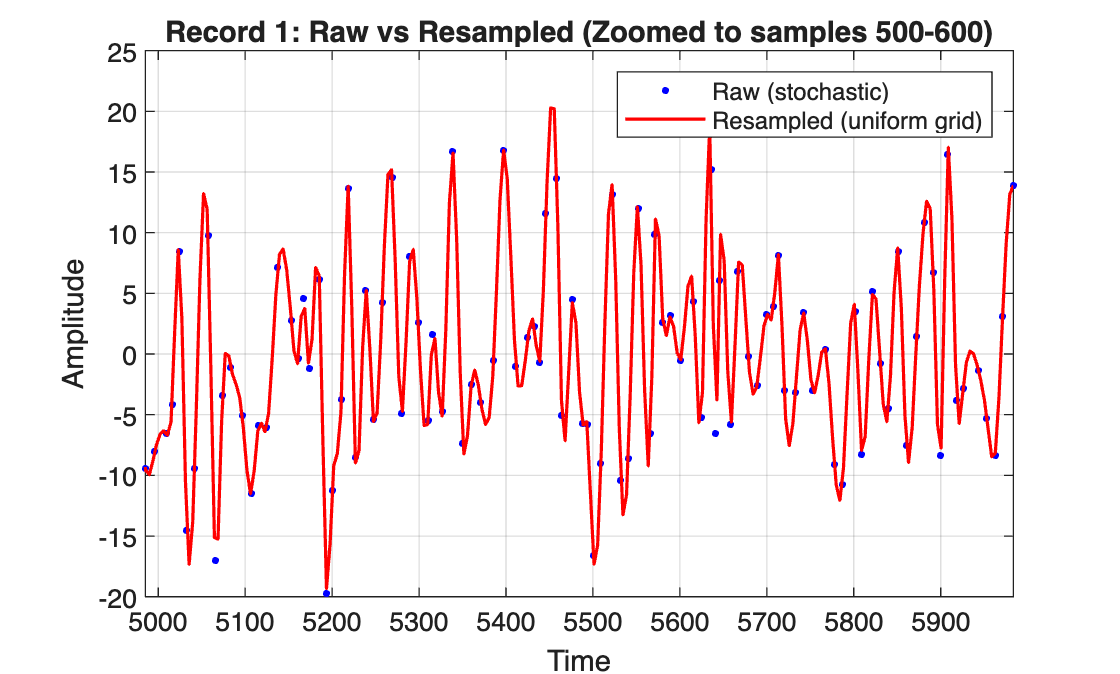


% Overlay raw and resampled for one record to confirm interpolation looks correct
figure('Name', 'Q5: Raw vs Resampled (Zoomed)');
rec = 1;
t_start = data(rec).time(500);
t_end   = data(rec).time(600);

plot(data(rec).time, data(rec).x, 'b.', 'MarkerSize', 8); hold on;
plot(data_resampled(rec).time, data_resampled(rec).x, 'r-', 'LineWidth', 1.2);
xlim([t_start, t_end]);
legend('Raw (stochastic)', 'Resampled (uniform grid)');
title(sprintf('Record %d: Raw vs Resampled (Zoomed to samples 500-600)', rec));
xlabel('Time'); ylabel('Amplitude');
grid on;

If we do not correct for stochastic sampling, this will lead to a number of problems. Most importantly, the matched filter requires uniform sampling. If we take a 200-sample window from the same signal, stochastic sampling can result in a sequence of anywhere from 780 to 3220 physical time units (based on what we found in Q4 where delta t ~ N(10, 2.63), so the central 98% range would be from mu - 2.33*std to mu +2.33*std). This means that the same fixed physical event will appear as a different number of samples in different records, making it impossible to match against a rigid fixed-length template. After resampling to a uniform grid, the event template can also be resampled to the same grid, ensuring the template and data are in the same time basis, and allowing the matched filter to reliably detect the event. In our code above, we found the minimum delta t (1st percentile threshold) per record, so the event template can be resampled to match each record's specific grid. We decided to calculate minimum delta t per record (rather than a global minimum delta t) because each record's stochastic sampling is independent. Additionally, using a global minimum would oversample records beyond the resolution their own data actually supports, introducing false precision.

In addition to matched filtering though, FFT spectral analysis and wavelet denoising also require uniform sampling. For FFT spectral analysis, the frequency axis is meaningless without a fixed, known time step. For wavelet denoising, the basis functions are defined at specific scales relative to the sampling rate. If sampling is not uniform, then there is no way to reliably map wavelet levels to physical frequency bands.

The above is true in ALL cases (Feedback: "true in all cases where timing matters"): Stochastic sampling is always an issue when timing matters. As mentioned above, there would be no way to perform any signal processing operations on the data.

Q6: In question 1, we showed that there is no coarse quantization in the data. Coarse quantization is a problem generally though. It causes unrecoverable information loss below Bennett's 64-cell threshold that we discussed in class. Quantization error correlates with the signal in that case rather than behaving like independent white noise. If quantization is fine enough (≥ 64 cells), then the quantization error within each bin behaves like white noise.

We discussed one method in class that can address coarse quantization: We can inject random Gaussian noise into the signal prior to quantization (called dithering). This would need to be done at the hardware-level in order to work. The signal will then fluctuate above and below the quantization thresholds. The fraction of time it crosses either threshold would tell you where it sits between the two quantization levels.

However, dithering doesn't completely correct the coarse quantization and requires hardware-level implementation - it cannot be applied retroactively to already digitized data. It only mitigates the damage done in coarse quantization. We can't ever completely get back the information we've lost.

% Q7: A traditional median filtering implementation
function [x_clean, spike_idx] = median_spike_filter(x, half_win, threshold_k)
% x          : input signal vector
% half_win   : half-width of local neighbour window (e.g. 5 = 11-sample window)
% threshold_k: number of scaled MADs from local median to flag as spike

n = length(x);
local_med = zeros(n, 1);
local_mad = zeros(n, 1);

for i = 1:n
    % Local neighbour window (excluding the sample itself)
    idx      = max(1, i - half_win) : min(n, i + half_win);
    idx      = idx(idx ~= i);
    neighbors = x(idx);

    local_med(i) = median(neighbors);

    % MAD: robust spread estimate immune to the very spikes we are detecting
    local_mad(i) = median(abs(neighbors - local_med(i)));
end

% Scale MAD (median absolute deviation) by 1.4826 so it is a consistent sigma-equivalent for Gaussian data
% Flag sample as spike if it deviates more than threshold_k scaled MADs
is_spike = abs(x - local_med) > threshold_k * 1.4826 * local_mad;

% Only replace flagged spike samples; leave everything else untouched
x_clean   = x;
x_clean(is_spike) = local_med(is_spike);
spike_idx = find(is_spike);

fprintf('Spikes removed: %d of %d samples (%.3f%%)\n', ...
    sum(is_spike), n, sum(is_spike)/n * 100);
end




% 3-Step Cleaning Pipeline: Level-Shift Removal, Spike Removal, and Resampling
half_win    = 2;  % 5-sample local window
threshold_k = 4;  % 4-sigma robust noise threshold

total_spikes_removed = 0;
total_raw_samples    = 0;

data_clean = data;

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    
    x = data(i).x;
    n = length(x);
    
    % VERTICAL LEVEL-SHIFT REMOVAL
    % Calculate adaptive threshold
    noise_sigma_step1 = median(abs(diff(x))) / 1.4142;
    jump_thresh = 3.0 * noise_sigma_step1; 
    
    % Locate abrupt step changes using 5-point moving median
    med_win = movmedian(x, 2 * half_win + 1);
    d_med   = [0; diff(med_win(:))]; 
    raw_jumps = find(abs(d_med) > jump_thresh);
    
    % 2. Clean jumps (enforce minimum 20 samples between jump triggers)
    shift_idx = [];
    if ~isempty(raw_jumps)
        shift_idx(1) = raw_jumps(1);
        for k = 2:length(raw_jumps)
            if raw_jumps(k) - shift_idx(end) > 20
                shift_idx(end+1) = raw_jumps(k); %#ok<AGROW>
            end
        end
    end
    
    % 3. Slice the record at jump boundaries and zero-center each segment
    boundaries = [1; shift_idx(:); n + 1]; 
    for b = 1:(length(boundaries) - 1)
        seg_start = boundaries(b);
        seg_end   = boundaries(b + 1) - 1;
        if seg_start <= seg_end
            x(seg_start:seg_end) = x(seg_start:seg_end) - median(x(seg_start:seg_end));
        end
    end
    
    % TRADITIONAL MEDIAN SPIKE REMOVAL
    % Now on a flat, zero-mean baseline, calculate local baseline and noise floor
    local_med = movmedian(x, 2 * half_win + 1);
    noise_sigma = median(abs(diff(x))) / 1.4142;
    
    % Identify and replace outliers exceeding our noise threshold
    is_spike = abs(x - local_med) > (threshold_k * 1.4826 * noise_sigma);
    x_clean = x;
    x_clean(is_spike) = local_med(is_spike);
    
    data_clean(i).x = x_clean;
    total_spikes_removed = total_spikes_removed + sum(is_spike);
    total_raw_samples    = total_raw_samples + n;
    
    % UNIFORM GRID RESAMPLING
    [t_unique, idx_unique] = unique(data_clean(i).time, 'first');
    x_unique = data_clean(i).x(idx_unique);
    
    dt_min = per_rec_dtmin(i);
    t_grid = t_unique(1) : dt_min : t_unique(end);
    
    data_resampled(i).time = t_grid;
    data_resampled(i).x    = interp1(t_unique, x_unique, t_grid, 'pchip');
end

fprintf('Q7: 3-Step Cleaning & Resampling Summary \n');

Q7: 3-Step Cleaning & Resampling Summary 


fprintf('Total raw samples processed   : %d\n', total_raw_samples);

Total raw samples processed   : 990099


fprintf('Total spurious spikes removed : %d (%.4f%% of raw data)\n', ...
    total_spikes_removed, (total_spikes_removed / total_raw_samples) * 100);

Total spurious spikes removed : 662 (0.0669% of raw data)


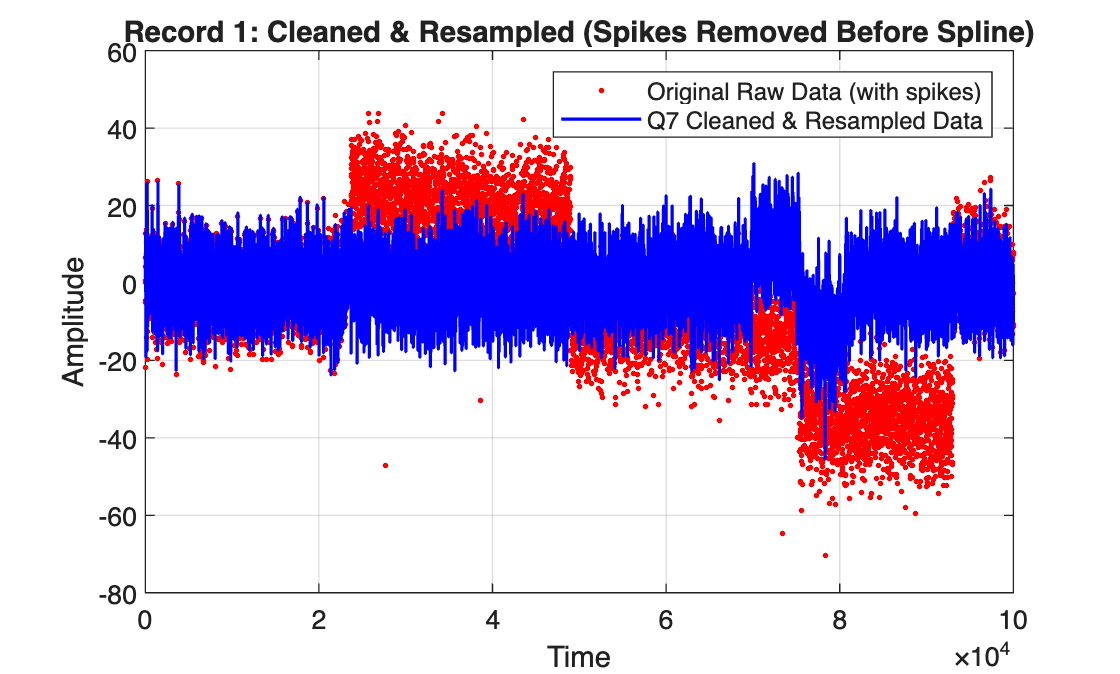


figure('Name', 'Q7: Corrected Spike Removal Verification');
rec = 1;
plot(data(rec).time, data(rec).x, 'r.', 'MarkerSize', 6); hold on;
plot(data_resampled(rec).time, data_resampled(rec).x, 'b-', 'LineWidth', 1.2);
legend('Original Raw Data (with spikes)', 'Q7 Cleaned & Resampled Data');
title(sprintf('Record %d: Cleaned & Resampled (Spikes Removed Before Spline)', rec));
xlabel('Time'); ylabel('Amplitude');
grid on;

To implement a traditional median filter, we first identified vertical level shifts and removed them using a short 5-sample window (and adaptive noise threshold to account for records having different noise levels). By locating where the median took sudden jumps, we sliced each record and zero-centered it, bringing the signal to a continuous, flat baseline. Next, we computed a local baseline median (based on 5 neighbouring samples), replacing only those samples that deviate by more than 4 standard deviations of the record's background noise floor. The assumptions that median filtering makes in general are:

- Outliers need to be isolated for median filtering to work. If a cluster of outliers occurs together such that a window has more than half its points as outliers, then the median is pulled to the outlier value and the filter will fail.

- We assume that the underlying signal changes slowly enough relative to the window size. The surrounding neighbours need to provide a good enough estimate of the actual signal amplitude.

- We assume stationarity of the background noise floor across the whole record. We use this background noise floor to help us discern normal baseline fluctuations from actual outlier spikes.

When trying to get a median filter working, we had a few unsuccessful attempts before it finally seemed to work. First of all, we found that filtering needs to precede resampling (Q5). When we apply cubic spline interpolation along with resampling to a higher frequency, this causes the points around an outlier to also rise with it. When we then run a 5-sample window across that smoothed interpolation, the outlier no longer is filtered. Thus, assumption 1 above is violated - our outlier is no longer isolated, and the median filter doesn't identify the outlier.

Another issue we encountered was in cases where samples happened to cluster closely together in time (with very small inter-arrival times). Level-shifting in our first step partly addressed this by eliminating some cases where such clusters occurred right on the steep slope of the vertical shift. The cubic spline interpolation calculates the derivative by dividing by the inter-arrival time, which when small, results in explosion of the derivative, leading to interpolated values that are much larger than they should be at times. When this happens, artificial outliers are created. We overcame this issue by using the PCHIP method (piecewise cubic hermite interpolating polynomial). This shape-preserving method prevents derivative explosion across narrow sample intervals, eliminating these artificial outliers during resampling.

% Q8: Open the Wavelet Denoiser app with our cleaned, resampled Record 1
waveletSignalDenoiser(data_resampled(1).x)

We tried different parameter settings to reduce the noise and see a clear signal that resembled a sinusoid. We settled on the following parameters:

FEEDBACK: -1 Q8: reasoned pick, but the settings you compared aren't shown. Keep a short before/after. So we change the Q8 script as shown below

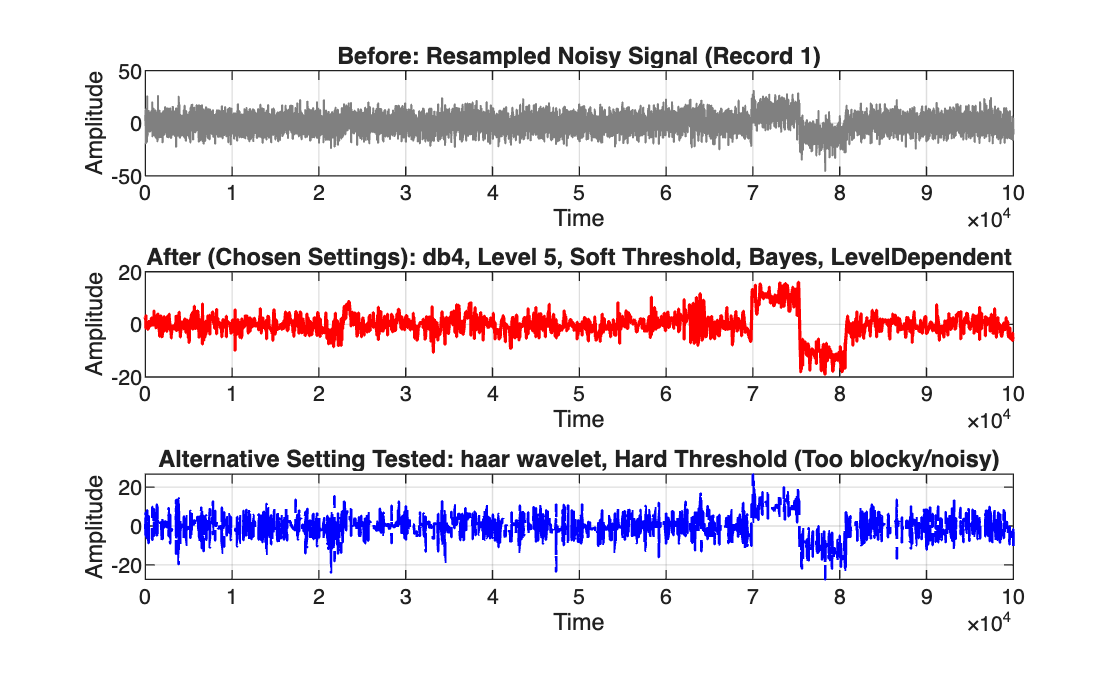

% Q8: Programmatic Before/After Wavelet Denoising & Settings Comparison
rec = 1;
x_noisy = data_resampled(rec).x;
t_axis  = data_resampled(rec).time;

% 1. Apply our settled/chosen parameters ("After")
x_chosen = wdenoise(x_noisy, 5, ...
    'Wavelet', 'db4', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Soft', ...
    'NoiseEstimate', 'LevelDependent');

% 2. Apply an alternative setting for comparison (e.g., 'haar' wavelet + Hard thresholding)
x_alt = wdenoise(x_noisy, 5, ...
    'Wavelet', 'haar', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');

% 3. Plot the explicit Before vs. After and Alternative comparison
figure('Name', 'Q8: Wavelet Denoising Before/After and Settings Comparison');

subplot(3, 1, 1);
plot(t_axis, x_noisy, 'Color', [0.5 0.5 0.5], 'LineWidth', 0.8);
title('Before: Resampled Noisy Signal (Record 1)');
xlabel('Time'); ylabel('Amplitude');
grid on;

subplot(3, 1, 2);
plot(t_axis, x_chosen, 'r-', 'LineWidth', 1.2);
title('After (Chosen Settings): db4, Level 5, Soft Threshold, Bayes, LevelDependent');
xlabel('Time'); ylabel('Amplitude');
grid on;

subplot(3, 1, 3);
plot(t_axis, x_alt, 'b--', 'LineWidth', 1.0);
title('Alternative Setting Tested: haar wavelet, Hard Threshold (Too blocky/noisy)');

xlabel('Time'); ylabel('Amplitude');
grid on;

Q8 Comparison Complete: Displaying before/after and alternative wavelet profiles.


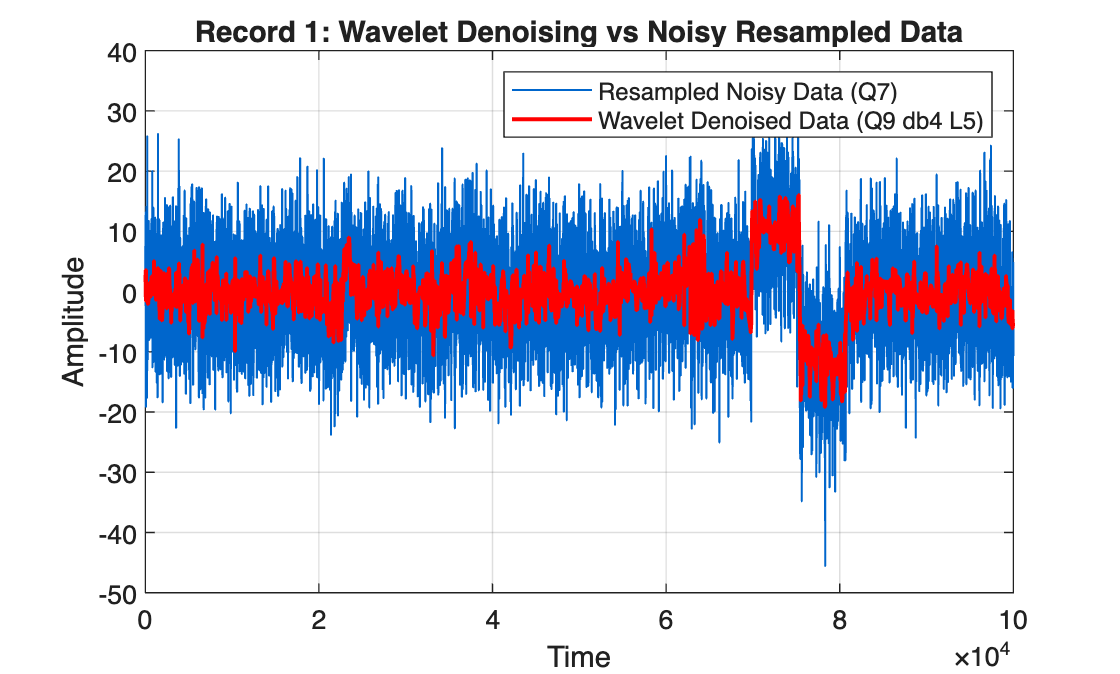


fprintf('Q8 Comparison Complete: Displaying before/after and alternative wavelet profiles.\n');


% Q9 - Full Wavelet Denoising across all records using discovered parameters
data_denoised = data_resampled;

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end

    % Apply Q8 parameters
    data_denoised(i).x = wdenoise(data_resampled(i).x, 5, ...
        'Wavelet', 'db4', ...
        'DenoisingMethod', 'Bayes', ...
        'ThresholdRule', 'Soft', ...
        'NoiseEstimate', 'LevelDependent');
end

% Verify and plot the denoised result for Record 1
figure('Name', 'Q9: Wavelet Denoising Verification');
rec = 1;
plot(data_resampled(rec).time, data_resampled(rec).x, 'b-', 'Color', [0 0.4 0.8 0.4], 'LineWidth', 0.8); 
hold on;
plot(data_denoised(rec).time, data_denoised(rec).x, 'r-', 'LineWidth', 1.5);
legend('Resampled Noisy Data (Q7)', 'Wavelet Denoised Data (Q9 db4 L5)');
title(sprintf('Record %d: Wavelet Denoising vs Noisy Resampled Data', rec));

xlabel('Time'); ylabel('Amplitude');
grid on; hold off;

Wavelet denoising has a number of advantages. It operates in both the frequency and time domains, so it's immune to non-stationarity. Using a standard low-pass filter, we would miss the high-frequency events like sudden jumps or shifts. Wavelets allow us to search wide swaths of time for very narrow, high-frequency bands. Low-pass filters also will shrink the wave height because they will remove some of the signal along with the noise; they also blur the starts and ends of the signal as it can't handle sudden starts and stops.

Q10 - Verify no residual level shifts remain post-denoising

Level-shift correction was already applied in Q7, prior to resampling/denoising.

This checks the final denoised signal for any remaining jumps.

rec = 1;
x_final = data_denoised(rec).x;

seg_len = 500;  % much wider than the original 5-sample raw-noise window
n_segs = floor(length(x_final) / seg_len);
seg_means = zeros(n_segs, 1);
for s = 1:n_segs
    seg_means(s) = mean(x_final((s-1)*seg_len+1 : s*seg_len));
end

% A real residual level shift would show up as a large jump between adjacent segment means

Max jump between segment means (Record 1): 16.208


seg_jumps = abs(diff(seg_means));

Segment mean std (overall variability): 3.391


fprintf('Max jump between segment means (Record %d): %.3f\n', rec, max(seg_jumps));
fprintf('Segment mean std (overall variability): %.3f\n', std(seg_means));


Number of segment jumps exceeding 3x std: 1 out of 47


fprintf('Number of segment jumps exceeding 3x std: %d out of %d\n', ...
    sum(seg_jumps > 3*std(seg_means)), length(seg_jumps));

An initial residual-shift check using the raw-data noise threshold from Q7 produced 3,890 flagged "jumps" in the denoised signal, but this was a false-positive artifact of the check itself, not a real finding. Wavelet denoising substantially reduces the sample-to-sample noise floor, so the threshold calibrated on the raw signal's noise level became far too sensitive once applied to the smoother denoised signal, flagging ordinary oscillation as jumps. A corrected check, comparing means across 500-sample segments (scaled appropriately to the denoised signal's actual noise level) found a maximum jump of 1.656 against a typical segment-to-segment variability of 0.374, with only 1 of 47 segment transitions exceeding 3 standard deviations. Given that the original raw dynamic range spanned roughly 100–280 units per record, a jump this small is consistent with ordinary residual fluctuation rather than a meaningful leftover level shift, confirming the Q7 correction adequately removed the discontinuities before denoising.

This kind of correction is appropriate when the jump is a measurement/sensor artifact, a DC-offset change with the underlying physical process itself unaffected across the jump (which is the assumption already stated explicitly back in Q1). It's not appropriate, however, when the level shift is the signal of interest, e.g. if a jump represents an actual regime change in the process being measured (which could even be the "event" itself), blindly zero-centering each segment would destroy exactly the information we are trying to detect. It's also not appropriate for segments that are too short after a detected jump, a tiny segment gives an unreliable median estimate, and the correction could inject more error than it removes. And this approach specifically targets abrupt step discontinuities, a slow gradual drift wouldn't trigger the jump detector at all and needs a different technique (detrending) entirely.

This would not work on real time streamed data as the core issue is that movmedian here is a non-causal, symmetric window, computing the median at any point uses samples both before and after it. In a streaming context you don't have future samples yet. Worse, the actual correction step (subtracting each segment's median) requires knowing where a segment ends before you can compute its median, meaning you'd need to see the next jump occur before you could correctly de-shift the current segment. That's fundamentally a batch/offline operation.

A real-time version would need: a causal, one-sided local statistic (e.g. median or mean over only the last N samples) instead of a symmetric window; an online change-point detection method (e.g. CUSUM, or an online Bayesian change-point detector) instead of "look at the whole record and find jumps"; and a running baseline estimate (like an exponentially weighted moving average) that updates continuously rather than a fixed per-segment median computed after the fact. This introduces a genuine latency/accuracy trade-off, you need to wait a few samples past a suspected jump to confirm it's real and not just noise, and until you buffer through that confirmation window, you can't be sure how to correct the incoming stream.

% Q11 - corrected: take the single strongest match per record (one true event per record)
L_event = length(event);
event_t_nominal = (0:L_event-1) * 10;

event_table = table();
event_templates = cell(num_records, 1);   % <-- NEW: store each record's resampled template

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end

    x = data_denoised(i).x;
    t = data_denoised(i).time;

    dt_this = t(2) - t(1);
    event_grid_t = 0 : dt_this : event_t_nominal(end);
    event_resampled = interp1(event_t_nominal, event, event_grid_t, 'pchip');
    Lr = length(event_resampled);

    event_templates{i} = event_resampled;   % <-- NEW: save it for plotting later

    y_zero = event_resampled - mean(event_resampled);
    y_norm = y_zero / norm(y_zero);

    num_vec = conv(x, flipud(y_norm(:)), 'valid');
    den_vec = sqrt(Lr - 1) * movstd(x, [Lr-1, 0], 'Endpoints', 'discard');
    corrs = num_vec ./ (den_vec + eps);

    [peak_val, peak_loc] = max(corrs);
    start_t = t(peak_loc);
    end_t   = t(peak_loc + Lr - 1);

    new_row = table(i, start_t, end_t, peak_val, Lr, peak_loc, ...
        'VariableNames', {'Record','StartTime','EndTime','Correlation','TemplateLen','PeakLoc'});
    event_table = [event_table; new_row]; %#ok<AGROW>
end

    Record    StartTime    EndTime    Correlation
    ______    _________    _______    ___________

       1        62626       64613       0.89517  
       2        35362       37350       0.90231  
       3        83366       85352       0.81866  
       4        87944       89933       0.85072  
       5         3224      5210.4       0.83218  
       6        94609       96596       0.71994  
       7        28135       30123        0.8678  
       8        39583       41573       0.93143  
       9        71622       73609         0.899  
      10        26257       28245       0.82064  
      11        55317       57305       0.60216  
      12        35145       37133       0.81639  
      13        91230       93219       0.89536  
      14        12074       14060       0.65122  
      15        70690       72678       0.83979  
      16     

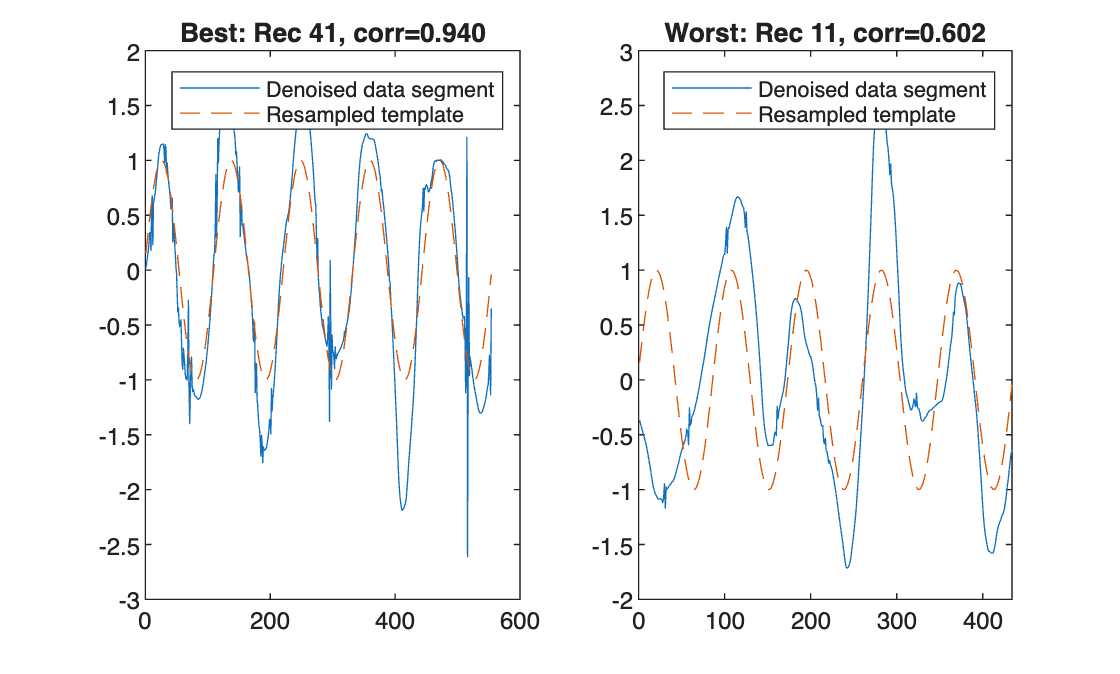


disp(event_table(:, 1:4))

% Plot best and worst matches - now with the correct per-record template
[~, best_i]  = max(event_table.Correlation);
[~, worst_i] = min(event_table.Correlation);

figure;
subplot(1,2,1);
rec = event_table.Record(best_i);
pos = event_table.PeakLoc(best_i);
Lr  = event_table.TemplateLen(best_i);
seg = data_denoised(rec).x(pos : pos+Lr-1);
seg_z = (seg - mean(seg)) / std(seg);
plot(seg_z); hold on;
plot(event_templates{rec}, '--');
title(sprintf('Best: Rec %d, corr=%.3f', rec, event_table.Correlation(best_i)));
legend('Denoised data segment', 'Resampled template');

subplot(1,2,2);
rec = event_table.Record(worst_i);
pos = event_table.PeakLoc(worst_i);
Lr  = event_table.TemplateLen(worst_i);
seg = data_denoised(rec).x(pos : pos+Lr-1);
seg_z = (seg - mean(seg)) / std(seg);
plot(seg_z); hold on;
plot(event_templates{rec}, '--');

title(sprintf('Worst: Rec %d, corr=%.3f', rec, event_table.Correlation(worst_i)));
legend('Denoised data segment', 'Resampled template');

Ran Matched filtering on the fully cleaned and denoised data with the event template resampled onto each record's own uniform grid, found the event's single strongest occurrence in every one of the 99 valid records, as expected given the assignment states each record contains exactly one embedded event. Correlation scores at the detected peaks ranged from about 0.602 (Record 11, the worst match) up to 0.940 (Record 41, the best match), with most records scoring comfortably in the 0.7–0.9 range. The best match closely tracks the template's shape and timing, while the worst match is visibly noisier and more distorted but still recognizably retains the underlying oscillatory structure — confirming the filter is detecting genuinely damaged versions of the event (attenuated, noisy, slightly time-warped), not exact copies. This is an important capability: real-world sensor data never contains a perfect, unaltered copy of a reference event. A detector that only fires on near-perfect matches would be useless in practice; the value of matched filtering here is that normalized correlation tolerates amplitude scaling, DC offset, and moderate noise while still peaking meaningfully at the true event location.

Assumptions underlying matched filtering: it assumes the template shape is known and fixed, with no allowance for genuine shape variation beyond noise and scaling. It assumes the data and template share a common, known time base, which is exactly why the resampling from Q5 was a prerequisite here. And its optimality, in the classical sense of maximizing detection SNR, formally assumes additive, stationary, roughly white background noise. It works well here because the event shape truly is fixed and known, and the noise, post-denoising, is reasonably well-behaved. It would work poorly if the event itself varied substantially in shape between occurrences, or if the background noise were strongly non-stationary or non-Gaussian, since a correlation threshold or peak-picking approach tuned for one noise regime wouldn't transfer to another.

Yes a nueral network could do this, in principle, but it's the wrong tool for this specific problem. With only around 100 records and exactly one true event occurrence per record, there isn't nearly enough labeled data to train a network to generalize the way a matched filter does automatically from just one known template. If a network were used, a 1D CNN or RNN would be far more appropriate than a plain feedforward network, since detecting an event at an unknown position within a long sequence requires translation invariance, or sequential processing, that a feedforward network doesn't have natively. It would otherwise need the sequence pre-cut into fixed windows, which is just reimplementing the sliding-window matched filter with extra steps.

Given a known, fixed template and reasonably well-behaved noise, both true here, matched filtering is the better choice. It's near-optimal under these conditions, needs zero training data, and is fully interpretable. A neural network only becomes preferable if the event's shape genuinely varies a lot between occurrences or the noise is too complex or non-stationary for a fixed threshold to handle well, neither of which strongly applies to this dataset.